## Clear Workspace

Optional step. We don't want variables from other scripts to interfere.

clear variables
clear offline_freq_band_selector
clc

## Load Data

Data was recorded using the Ripple system, and it was saved as a `.ns2` file. I am using a script written by Tyler to import the image into a MATLAB-readable format.

[head, data] = read_nsx_file('File', 'D:\FRM\research-data\emg-fatigue\datafile0022.ns5');

Loading 1.2 GB of data


## Validate Raw Data

Look at the Power Spectral Density and the Spectrogram using the Signal Analyzer app. Make sure there aren't any artifacts before proceeding.

Keep in mind that you will ususally have applied filters during the recording.

fs = head.Fs;
ch_idx = 1;
ch_signal = data(ch_idx, :);
fprintf("Data from channel %02d sampled at %d kHz.\n%.3f sec (%02.0f mins) total.", ch_idx, fs, length(ch_signal)/fs,length(ch_signal)/fs/60);

Data from channel 01 sampled at 30000 kHz.
600.882 sec (10 mins) total.

## Analyze Power Spectrum at Initial, Middle and End Points

base_offset = 30+5;
ch_window = 60;
idx_start = base_offset; 
idx_stop = idx_start + ch_window;
ch_signal_ini = ch_signal(1, idx_start*fs:idx_stop*fs);
idx_start = length(ch_signal)/fs/2 - ch_window/2; 
idx_stop = idx_start + ch_window;
ch_signal_mid = ch_signal(1, idx_start*fs:idx_stop*fs);

idx_stop = length(ch_signal)/fs - base_offset;
idx_start = idx_stop - ch_window; 
ch_signal_end = ch_signal(1, idx_start*fs:idx_stop*fs);

freq_lims = [1.35 1.35e3]; % Hz
[Pch_signal_ini, Fch_signal_ini] = pspectrum(double(ch_signal_ini), fs, 'FrequencyLimits',freq_lims);
[Pch_signal_mid, Fch_signal_mid] = pspectrum(double(ch_signal_mid), fs, 'FrequencyLimits', freq_lims);
[Pch_signal_end, Fch_signal_end] = pspectrum(double(ch_signal_end), fs, 'FrequencyLimits', freq_lims);

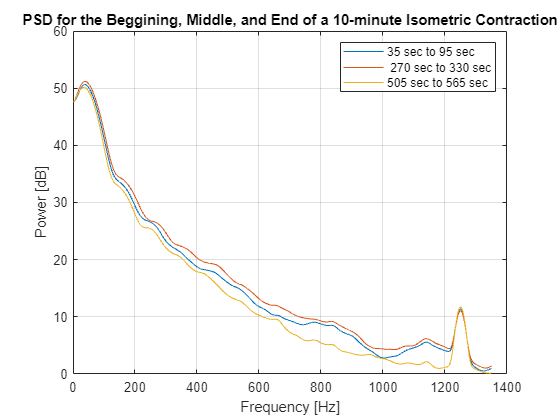

plot(Fch_signal_ini, pow2db([Pch_signal_ini Pch_signal_mid Pch_signal_end] ))

legend(["Initial","Middle","End"])

grid on
legend(["35 sec to 95 sec"," 270 sec to 330 sec","505 sec to 565 sec"])
title("PSD for the Beggining, Middle, and End of a 10-minute Isometric Contraction")
xlabel("Frequency [Hz]")
ylabel("Power [dB]")

power_diff_db = pow2db(Pch_signal_ini) - pow2db(Pch_signal_end) ;
adtest(power_diff_db)

ans = logical
   1


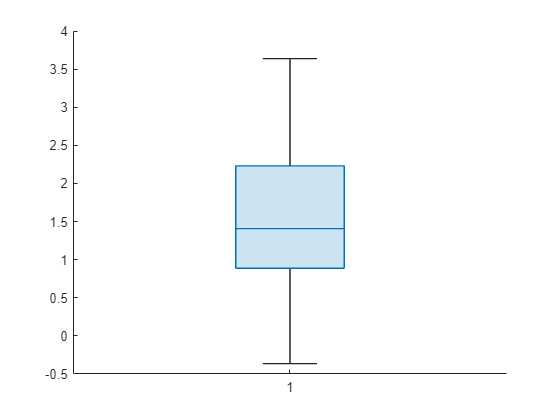

boxchart(power_diff_db)

prctile(power_diff_db,75)

ans = 2.2306

fatigue_candidates = (power_diff_db) >= 2.23;

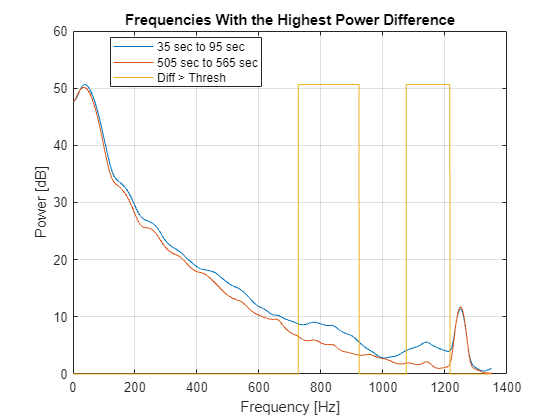

% all_db_powers = pow2db([Pch_signal_ini Pch_signal_mid Pch_signal_end]);
all_db_powers = pow2db([Pch_signal_ini Pch_signal_end]);

plot(Fch_signal_ini, [all_db_powers fatigue_candidates*max(all_db_powers,[], 'all')]);

xlabel("Frequency [Hz]")
ylabel("Power [dB]")

grid on
legend(["35 sec to 95 sec","505 sec to 565 sec","Diff > Thresh"])
legend("Position", [0.19681,0.79365,0.27143,0.11905])

title("Frequencies With the Highest Power Difference")

bin_idx = [0; abs(diff(fatigue_candidates))];
bin_idx = (bin_idx)>0;
fatigue_freqs = Fch_signal_ini(bin_idx)

fatigue_freqs = 1.0e+03 *

    0.7269
    0.9232
    1.0750
    1.2160


diff(fatigue_freqs)

ans =   196.2870
  151.8260
  140.9578


window_length = 100e-3*fs;
signal_length = length(ch_signal);
total_segments = floor(signal_length/window_length);
p0700 = zeros(total_segments,1);
p0800 = zeros(total_segments,1);
p1000 = zeros(total_segments,1);
p1100 = zeros(total_segments,1);

parfor i = 1:total_segments
    if i == 1
        idx_from = 1;
        idx_to = window_length;
    else
        idx_from = (i-1)*window_length+1;
        idx_to = i*window_length;
    end
    window_data = double(ch_signal(idx_from:idx_to))
    p0700(i) = bandpower(window_data, fs, [725 825]);
    p0800(i) = bandpower(window_data, fs, [825 925]);
    p1000(i) = bandpower(window_data, fs, [1025 1125]);
    p1100(i) = bandpower(window_data, fs, [1125 1225]);
end

figure()
time = 0:1:total_segments-1

time =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


time = window_length * time /fs

time =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


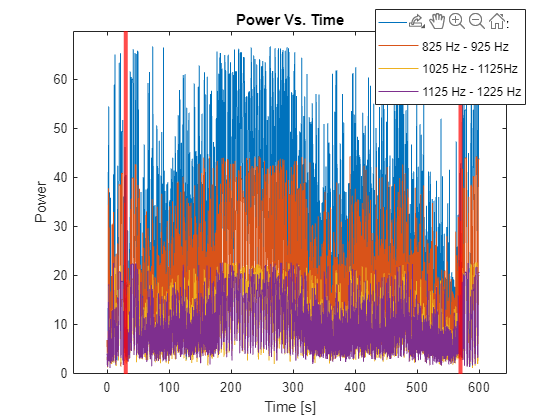

plot(time, [filloutliers(p0700, 'previous'), filloutliers(p0800, 'previous'), filloutliers(p1000, 'previous'), filloutliers(p1100, 'previous') ])
xline([30 570],'LineWidth',3,'Color', 'r')

xlim([-55 645])
ylim([-0.2 69.8])
ylim([-0.2 69.8])
legend(["725 Hz - 825 Hz","825 Hz - 925 Hz","1025 Hz - 1125Hz","1125 Hz - 1225 Hz"])
legend("Position", [0.64563,0.69484,0.26964,0.22976])
title("Power Vs. Time")
xlabel("Time [s]")
ylabel("Power")

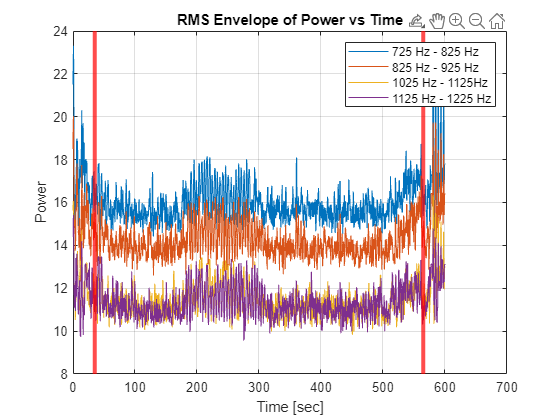

plot(time, [ ...
    envelope(pow2db(filloutliers(p0700, 'previous')),10, 'rms'), ...
    envelope(pow2db(filloutliers(p0800, 'previous')),10, 'rms'), ...
    envelope(pow2db(filloutliers(p1000, 'previous')),10, 'rms'), ...
    envelope(pow2db(filloutliers(p1100, 'previous')),10, 'rms') ...
    ])
xline([35 565],'LineWidth',3,'Color', 'r')

grid on
legend(["725 Hz - 825 Hz","825 Hz - 925 Hz","1025 Hz - 1125Hz","1125 Hz - 1225 Hz"])
title("RMS Envelope of Power vs Time")
xlabel("Time [sec]")
ylabel("Power")

signalAnalyzer([ch_signal_ini, ch_signal_mid, ch_signal_end] , 'SampleRate', fs)

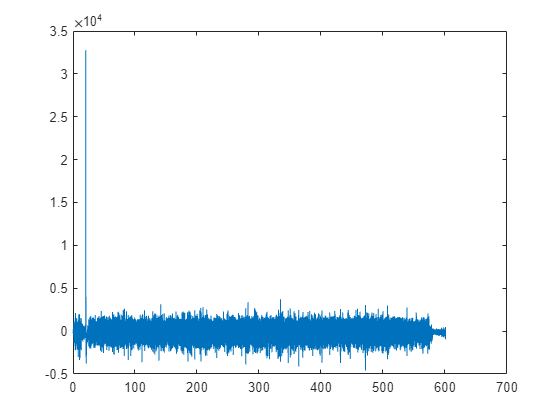

plot([0:length(ch_signal)-1]/fs, ch_signal)

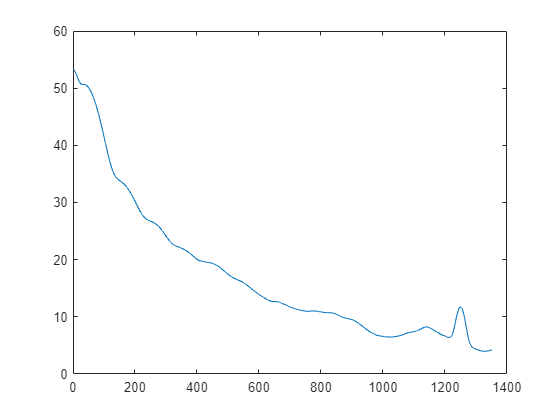

[Pch_signal, Fch_signal] = pspectrum(double(ch_signal), fs, 'FrequencyLimits',freq_lims);
plot(Fch_signal, pow2db(Pch_signal));